# Compito di tirocinio no. 1

#### Specifica da implementare

Si consideri il sistema  a tempo discreto


$$x\left(k+1\right)=A\;x\left(k\right)+B\;u\left(k\right)$$


- Scrivere una funzione e MATLAB che, avendo come input $\left(A,B,\nu ,\bar{x} \right)$, dia come output (se esiste) il controllo $u\left(\cdot \right)$ che, partendo da $x\left(0\right)=0$, ottiene $x\left(\nu \right)=\bar{x}$, minimizzando l’indice di costo: $\displaystyle J_\nu(u(\cdot))=\sum_{h=0}^{\nu-1}||u(h)||_2^2$

- Utilizzando la funzione scritta al punto precedente, e scrivendone altre se opportuno, per un sistema raggiungibile caratterizzato da $A=\left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$

Mostrare l'andamento di $J_{\nu } \left(u^{\ast } \left(\cdot \right)\right)$ per $\nu =2,\ldots,\nu_{\max }$ scegliendo $\nu_{\max }$ in modo adeguato. Ripetere l'operazione per diversi valori di $\bar{x}$ sulla circonferenza unitaria e confrontare i risultati.

Visualizzare anche, almeno per alcuni casi scelti, gli andamenti di $u^{\ast } \left(\cdot \right)$ nell'intervallo $\left\lbrack 0,\nu -1\right\rbrack$ e della corrispondente risposta $x^{\ast } \left(\cdot \right)$ nell'intervallo $\left\lbrack 0,\nu \right\rbrack$.

Ripetere lo studio per diverse coppie $\left(\lambda_1 ,\lambda_2 \right)$ interpretando i risultati attraverso confronti tra i diversi casi studiati, per evidenziare analogie e differenze.

#### Algoritmo di calcolo del controllo ad energia minima

Ricordiamo che per il calcolo del controllo allo stato $\bar{x}$ ad energia minima a $\nu$ passi possiamo usare la seguente procedura

- calcolare la matrice di raggiungibilità a $\nu$ del sistema $\bar{P} =P_{\nu } \left(A,B\right)$

- calcolare la matrice quadrata e simmetrica $\bar{G} =\bar{P} {\bar{P} }^{\top }$

- se lo stato è nell'immagine di $\bar{G}$ (quindi anche nell'immagine di $\bar{P}$), trovare quel vettore $v$ per cui $\bar{G} v=\bar{x}$

- definire il vettore ${\left\lbrack \begin{array}{ccccc}
w_0  & w_1  & \cdots  & w_{\nu -2}  & w_{\nu -1} 
\end{array}\right\rbrack }^{\top } ={\bar{P} }^{\top } v$

- la soluzione al problema del controllo sarà allora data dalla funzione $u:k\mapsto w_{\nu -k-1}$

#### Funzione per il calcolo della matrice di raggiungibilità

Per il calcolo della matrice di raggiungibilità $P\left(A,\;B\right)$ uso la definizione della matrice di raggiungibilità: a partire dal blocco $P_0 =B$ definiamo iterativamente il blocco $P_{i+1} =A\cdot P_i$

Calcolato il blocco $P_n$ possiamo accodare per colonna i blocchi $P_i$ e avremmo la matrice di controllabilità $P\left(A,B\right)$

L'implementazione che utilizzeremo per il calcolo della matrice $P_k \left(A,B\right)$ può essere trovata nel file `calculatePmatrix.m`

A = ...
[   
    1   0   0   ;
    1   2   0   ;
    0   0   0   ;
];
B = ...
[   1   -1  ;
    0   0   ;
    0   0   ;
];
n = 2;

P = calculatePmatrix(A, B, n)

P =      1    -1     1    -1
     0     0     1    -1
     0     0     0     0


Siccome per il calcolo del controllo a minima energia avremmo in realtà bisogno della matrice $G_k \left(A,B\right)=P_k {\left(A,B\right)}^{\top } \cdot P_k \left(A,B\right)$ verrà usata la funzione descritta in `calculateGPmatrix.m` che, a partire dalle matrici $A,B$ calcola e ritorna sia la matrice $G_k \left(A,B\right)$ (primo valore  di ritorno) che $P_k \left(A,B\right)$ (secondo valore di ritorno)

[G, ~] = calculateGPmatrix(A, B, n)

G =      4     2     0
     2     2     0
     0     0     0


#### Calcolo della contro-immagine dello stato

Per quanto riguarda il terzo punto notiamo che, nel solo caso in cui $\det \;\bar{G} \;\not= \;0$, un vettore $v$ può essere sempre calcolato ponendo $v={\bar{G} }^{-1} \bar{x}$

Per poter calcolare $v$ nel caso più generale possibile innanzitutto calcoliamo la matrice pseudo-inversa di ${\bar{G} }^#$ e poniamo $v={\bar{G} }^# \bar{x}$, e in seguito verifichiamo che tale vettore effettivamente venga mappato sullo stato $\bar{x}$ via $\bar{G}$

Questa procedura è stata implementata nella funzione `invImg.m` che oltre a restituire il vettore $v$ restituisce anche la differenza tra $\bar{x}$ e l'immagine di $v$ sotto $\bar{G}$ (molto piccola quando $\bar{x} \in \textrm{Img}\left\lbrace \bar{G} \right\rbrace$)

b = orth(G)

b =    -0.8507   -0.5257
   -0.5257    0.8507
         0         0


x = [1; 0; 0];
[v, d] = invImg(x, G)

v =     0.5000
   -0.5000
         0


d = 3.1402e-16

#### Calcolo del controllo

Ora che possiamo (entro un certo errore) calcolare la contro-immagine di $\bar{x}$ sotto $\bar{G}$, possiamo finalmente calcolare il vettore $w$ e quindi il controllo $\bar{u} \left(\cdot \right)$

Il calcolo di $w$ e l'inversione dei suoi elementi per ottenere $\bar{u} \left(\cdot \right)$, a partire da $A,B,\nu ,\bar{x}$ (la funzione richiesta al punto 1.) è gestita dalla funzione `calculateReachCtrl.m `che oltre a restituire l'azione per il controllo a $\bar{x}$ restituisce anche l'indice di costo calcolato (la norma quadra di $u$)

[u, J] = calculateReachCtrl(A, B, n, x)

u =    -0.0000    0.5000
    0.0000   -0.5000


J = 0.5000

[u, J] = calculateReachCtrl(A, B, x)

u =    -0.0714    0.2143    0.3571
    0.0714   -0.2143   -0.3571


J = 0.3571

#### Caso studio sul calcolo del controllo

Analizziamo adesso la richiesta del punto 2: sappiamo che

- 
$$n=2,p=1$$


- il sistema è raggiungibile, quindi lo spazio degli stati raggiungibili equivale ad ${\mathbb{R}}^2$

Affinché un sistema con $A=\left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack$ e $B=\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$ sia raggiungibile dovremmo avere che $\textrm{rank}\left(P_2 \left(A,\;B\right)\right)=2$

Affinché $P_2 \left(A,B\right)=\left\lbrack \begin{array}{cc}
B & A\;B
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & \lambda_1 \\
1 & \lambda_2 
\end{array}\right\rbrack$ abbia rango 2 basta che $\lambda_1 \not= \lambda_2$ e la matrice simmetrica è facilmente calcolabile$G=\left\lbrack \begin{array}{cc}
1 & \lambda_1 \\
1 & \lambda_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & 1\\
\lambda_1  & \lambda_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1+\lambda_1^2  & 1+\lambda_1 \lambda_2 \\
1+\lambda_1 \lambda_2  & 1+\lambda_2^2 
\end{array}\right\rbrack$ che è sempre invertibile siccome il suo determinante è $\lambda_1^2 +\lambda_2^2 -2\lambda_1 \lambda_2 ={\left(\lambda_1 -\lambda_2 \right)}^2 \Rightarrow$ l'algoritmo per il calcolo del controllo può essere semplificato ma, per puri scopi dimostrativi nella prossima sezione verranno usate le stesse funzioni definite prima

l1 = 0;
l2 = 1.6;

A = ...
    [
        l1  0   ;
        0   l2  ;
    ];
B = [1; 1];
ph = deg2rad(53);
x = [cos(ph); sin(ph)];
nu = 17;
[u, J] = calculateReachCtrl(A, B, nu, x)

u =     0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.6018


J = 0.3622

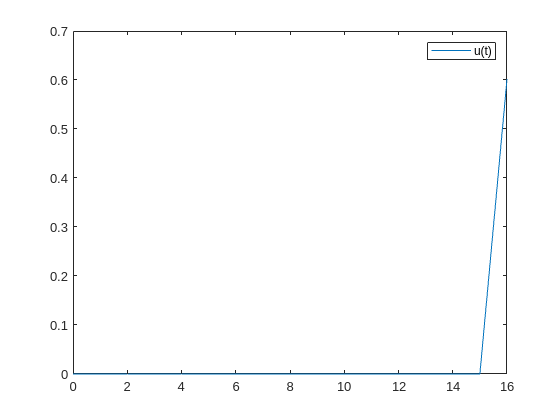

t = (0 : 1 : (nu - 1));
figure(1);
plot(t, u);
legend("u(t)");

#### Caso studio sull'andamento dell'indice di costo

Per questa sezione andremo a calcolare e graficare l'andamento del controllo nel tempo e dell'indice di costo minimo al variare del numero di passi $\nu$

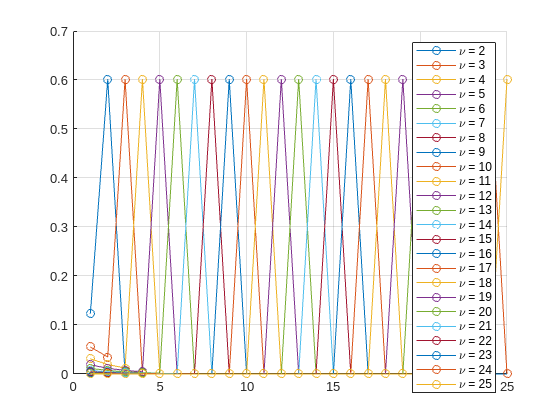

close;
figure(1);
hold on
grid;

numax = 25;
nu = (2 : 1 : numax);

Jvect = zeros(1, numax - 1);
u = zeros(1, numax);

for i = nu
    [u(1, 1 : i), Jvect(i - 1)] = calculateReachCtrl(A, B, i, x);
    
    plot([1, nu], u, "DisplayName", ("\nu = " + i), "Marker", "o");
    legend("-DynamicLegend");
end
hold off

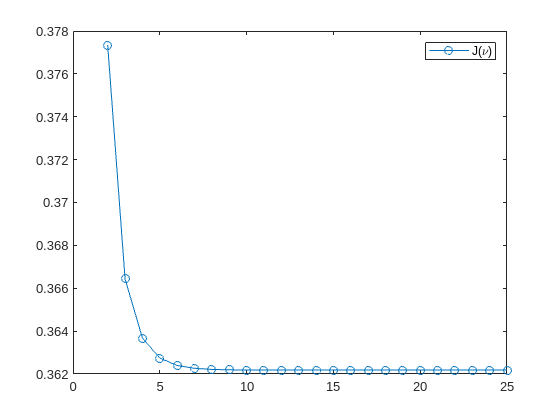

figure(2);
plot(nu, Jvect, "Marker", "o");
legend("J(\nu)");

#### Pannello di controllo completo

Questa sezione sarà dedicata al condensare tutte le variabili definite e usate nelle sezioni precedenti in un unico e completo pannello di controllo: sarà quindi possibile

- scegliere gli autovalori per la matrice $A$

- scegliere uno stato da raggiungere $\bar{x}$ sulla semicirconferenza unitaria (ramo positivo)

- scegliere un numero massimo di passi $\nu_{\max }$ per raggiungere $\bar{x}$

e quindi visualizzare

- la risposta nel tempo dello stato e dell'ingresso

- l'andamento dell'indice di costo minimo al variare del numero di passi $\nu$

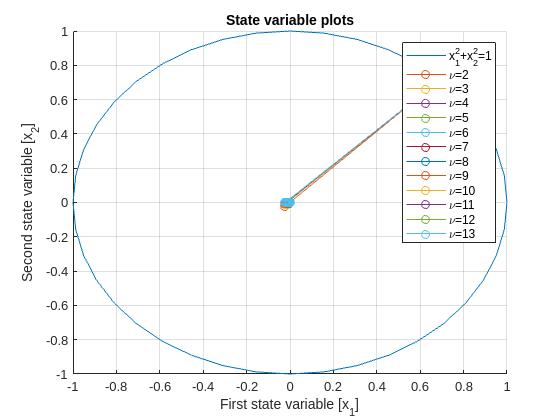

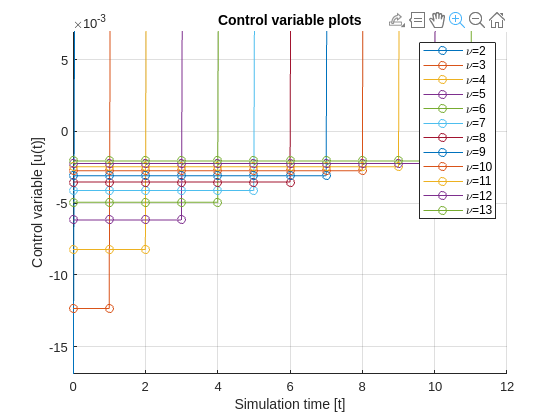

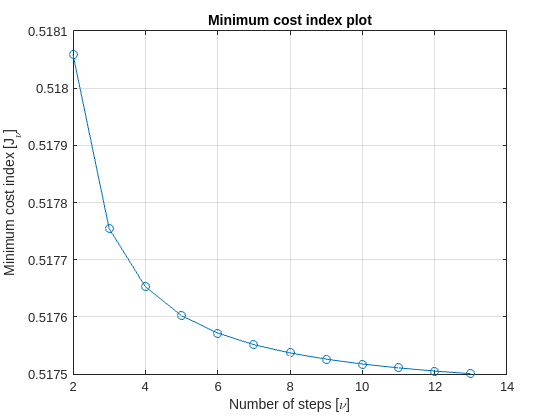

close all
clear
l1 = 1; l2 = 0; ph = 46; numax = 13;
J = plotEverything(l1, l2, ph, numax);